bode_plot_options = bodeoptions();
bode_plot_options.Grid = 'on';
%bode_plot_options.PhaseWrapping = 'on';

# Plant

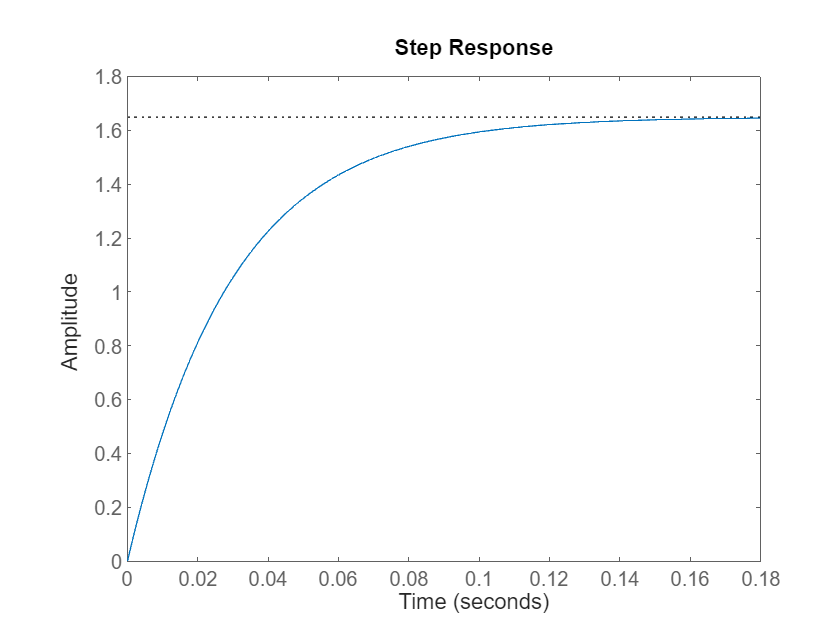

s = tf('s');
plant_tf = 55.99/(s+33.95);
step_response_parameters = stepinfo(plant_tf);
plant_ts = step_response_parameters.RiseTime;
step(plant_tf);

## Plant Discretization

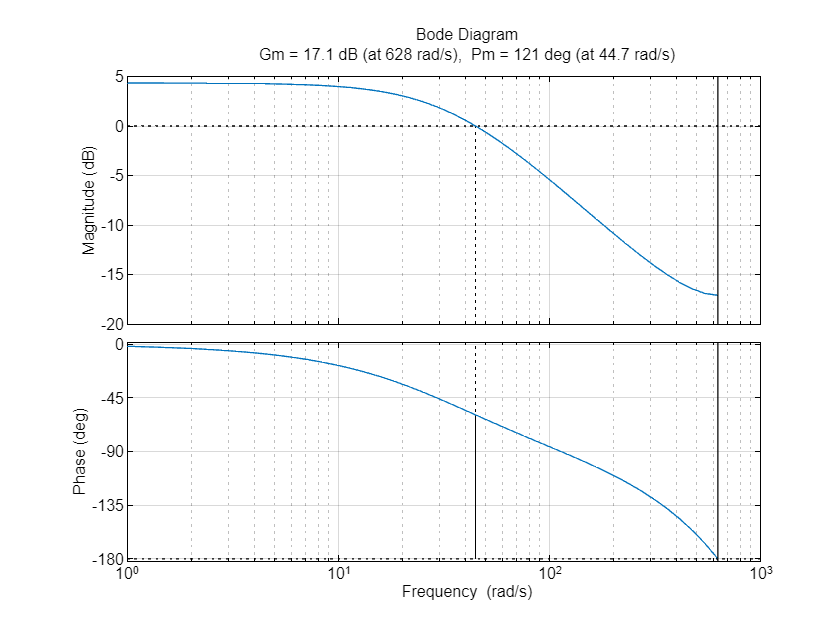

Ts = 0.005;
plant_tf_z = c2d(plant_tf,Ts,'zoh');
margin(plant_tf_z,bode_plot_options)

# Control Design

#### Parameters

Overshoot [Mp] <= 25%, Velocity Error [Ev] = 0, Pm >= 40°, Gm>=10dB

Controller type: 2 integrators and 2 lead compensators

## Integrators in z

2 integrators are assigned to get Ev=0, K is set to lower the negative phase margin and allow the lead compensators to fix the inestability created by the double integrators,

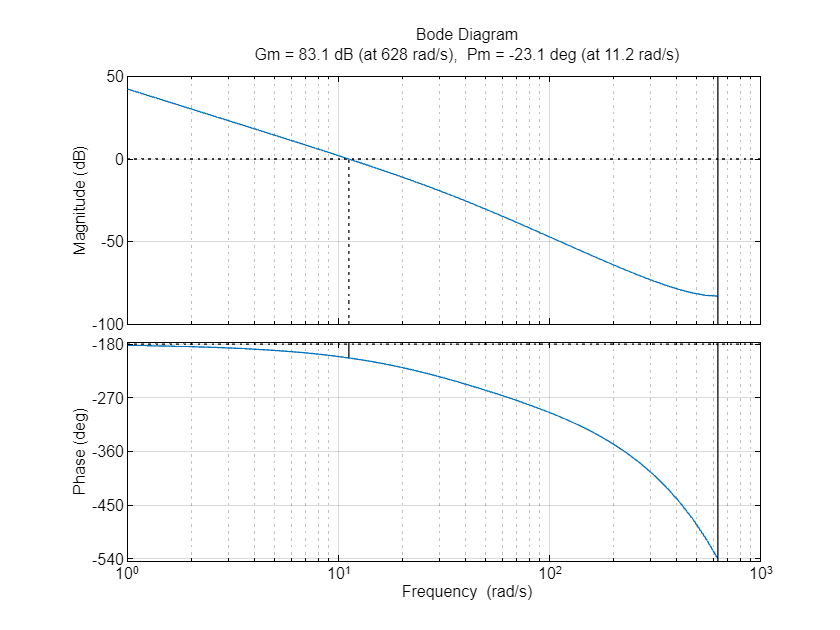

z = tf('z',0.005);
k = 0.002;
integ_ctrl_tf_z = k/((z-1)^2);
integ_ctrl_plant_tf_z = series(integ_ctrl_tf_z,plant_tf_z);
margin(integ_ctrl_plant_tf_z,bode_plot_options);

## W Transform for the plant plus the integrators

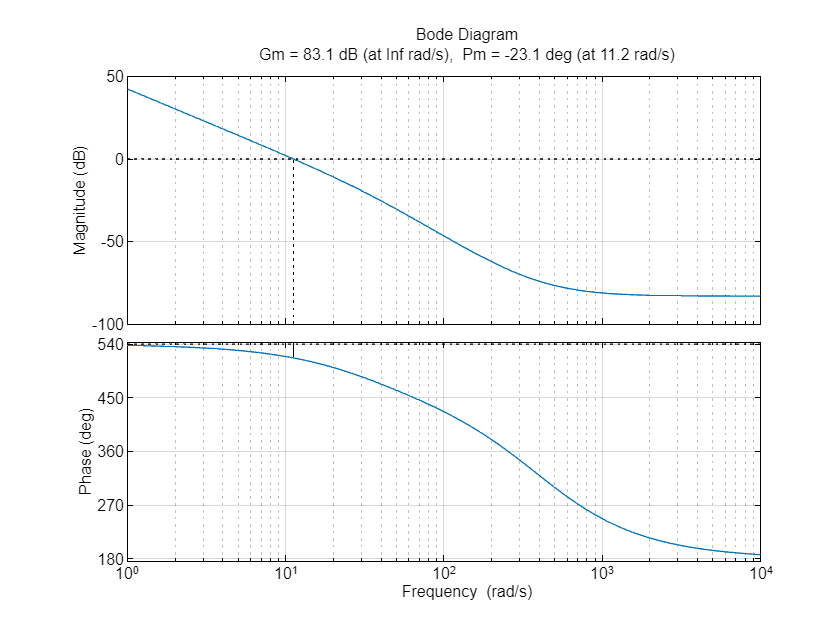

integ_ctrl_plant_tf_w = w_transform.z2w(integ_ctrl_plant_tf_z,Ts);
margin(integ_ctrl_plant_tf_w,bode_plot_options);

## First Lead Compensator in W

required_pm1 = 40+10-(-23.1);
b_1 = (1 + sind(required_pm1))/(1-sind(required_pm1));
disp("w1_crossover_gain: " + num2str(-10*log(b_1)));

w1_crossover_gain: -38.1355


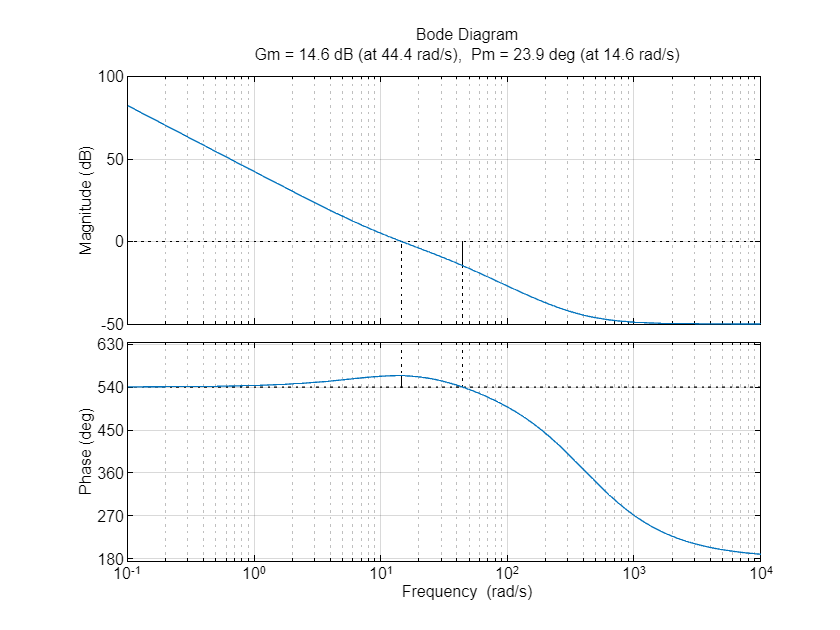

w1_crossover = 68;
T2_1=1/(sqrt(b_1)*w1_crossover);
lead_ctrl1_tf_w = (1+(b_1*T2_1*s))/(1+(T2_1*s));
margin(lead_ctrl1_tf_w*integ_ctrl_plant_tf_w,bode_plot_options);

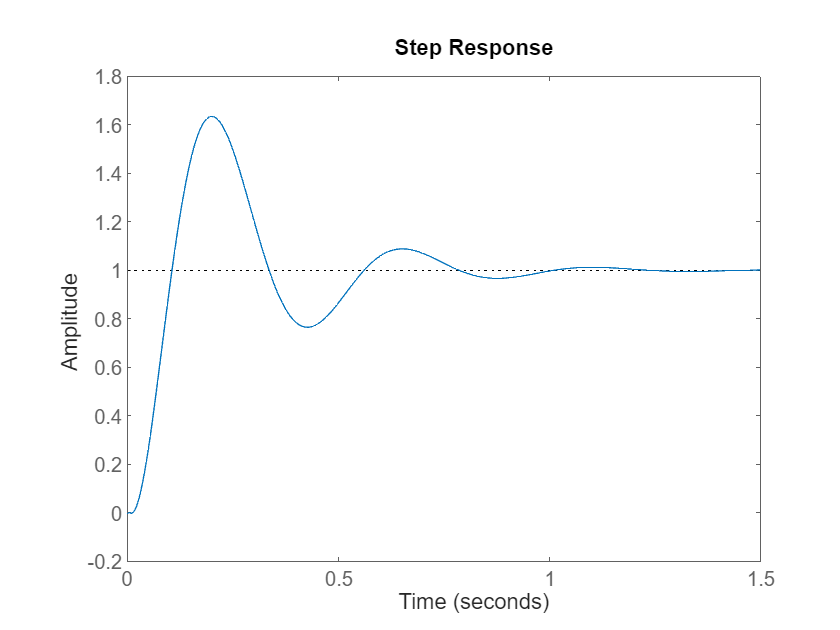

step(feedback(lead_ctrl1_tf_w*integ_ctrl_plant_tf_w,1));

## Second Lead Compensator in W

required_pm2 = 40+30-(23.9);
b_2 = (1 + sind(required_pm2))/(1-sind(required_pm2));
disp("w2_crossover_gain: " + num2str(-10*log(b_2)));

w2_crossover_gain: -18.1758


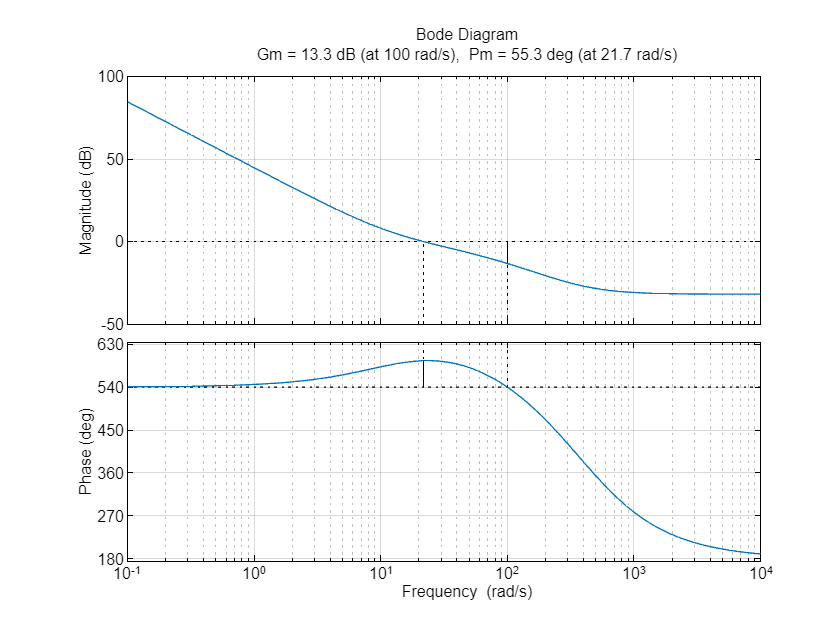

w2_crossover = 56.1; %rad/s
T2_2=1/(sqrt(b_2)*w2_crossover);
k2=1.3;
lead_ctrl2_tf_w = k2*(1+(b_2*T2_2*s))/(1+(T2_2*s));

margin(lead_ctrl2_tf_w*lead_ctrl1_tf_w*integ_ctrl_plant_tf_w,bode_plot_options);

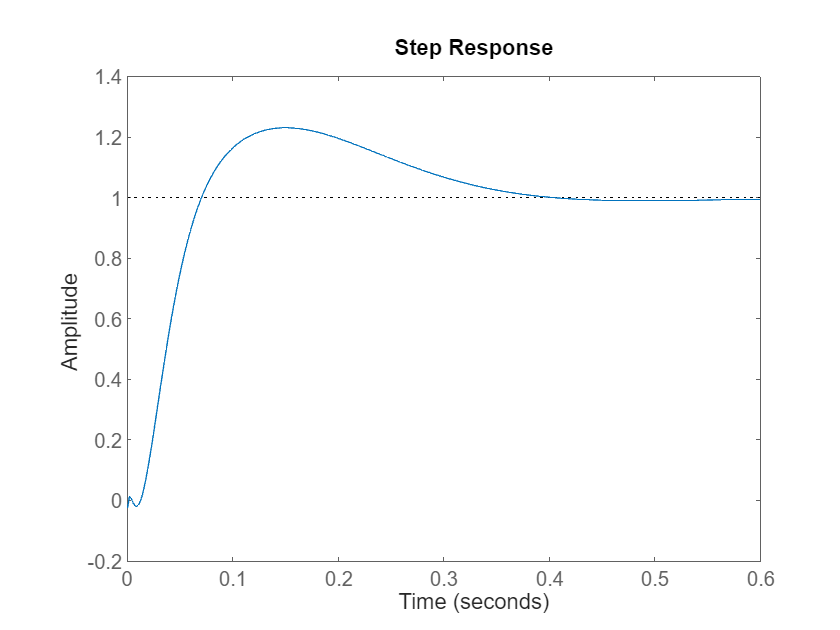

step(feedback(lead_ctrl2_tf_w*lead_ctrl1_tf_w*integ_ctrl_plant_tf_w,1));

disp(stepinfo(feedback(lead_ctrl2_tf_w*lead_ctrl1_tf_w*integ_ctrl_plant_tf_w,1)));

         RiseTime: 0.0414
    TransientTime: 0.3569
     SettlingTime: 0.3578
      SettlingMin: 0.9094
      SettlingMax: 1.2307
        Overshoot: 23.0723
       Undershoot: 2.5979
             Peak: 1.2307
         PeakTime: 0.1504



## Inverse W transform and Final Bode

lead_ctrl1_tf_z = w_transform.w2z(lead_ctrl1_tf_w,Ts);
lead_ctrl2_tf_z = w_transform.w2z(lead_ctrl2_tf_w,Ts);

#### Response of Closed Loop for discrete plant

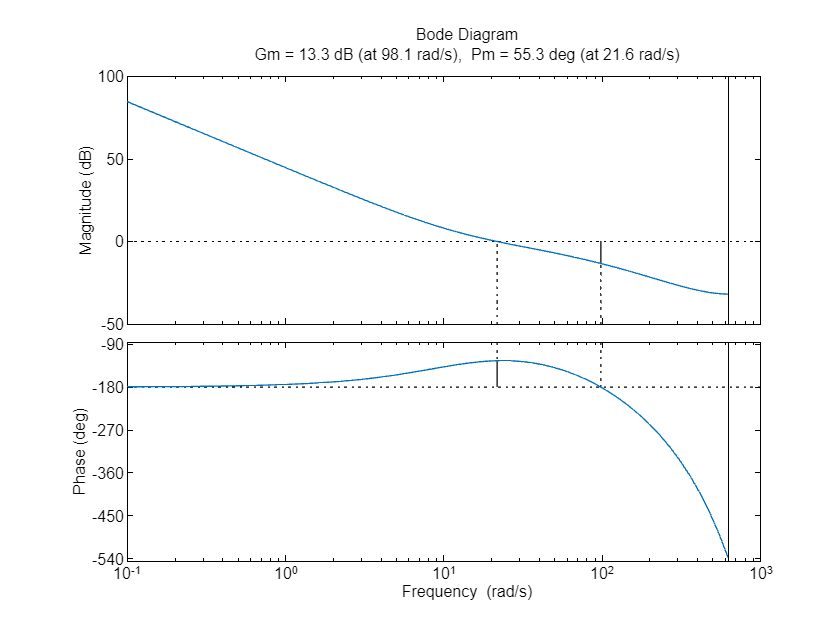

margin(lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_tf_z*plant_tf_z,bodeoptions);

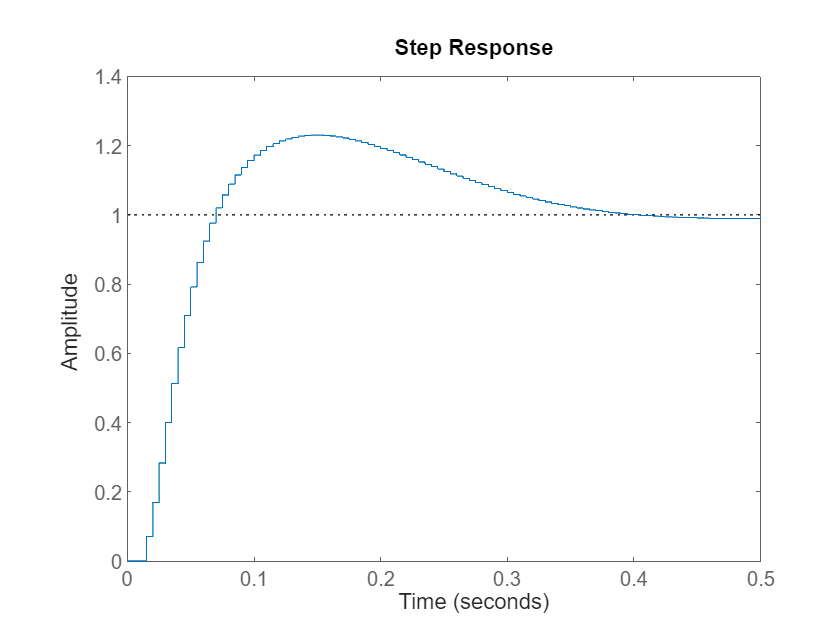

step(feedback(lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_tf_z*plant_tf_z,1));

disp(stepinfo(feedback(lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_tf_z*plant_tf_z,1)));

         RiseTime: 0.0400
    TransientTime: 0.3600
     SettlingTime: 0.3600
      SettlingMin: 0.9242
      SettlingMax: 1.2307
        Overshoot: 23.0707
       Undershoot: 0
             Peak: 1.2307
         PeakTime: 0.1450



#### Response of Closed Loop for continuous plant

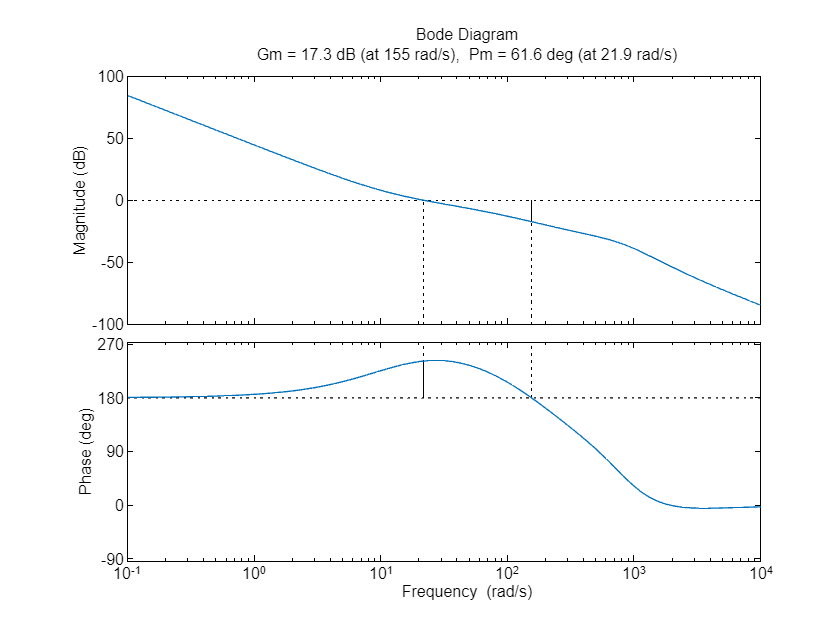

margin(d2c(lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_tf_z,'zoh')*plant_tf,bodeoptions);

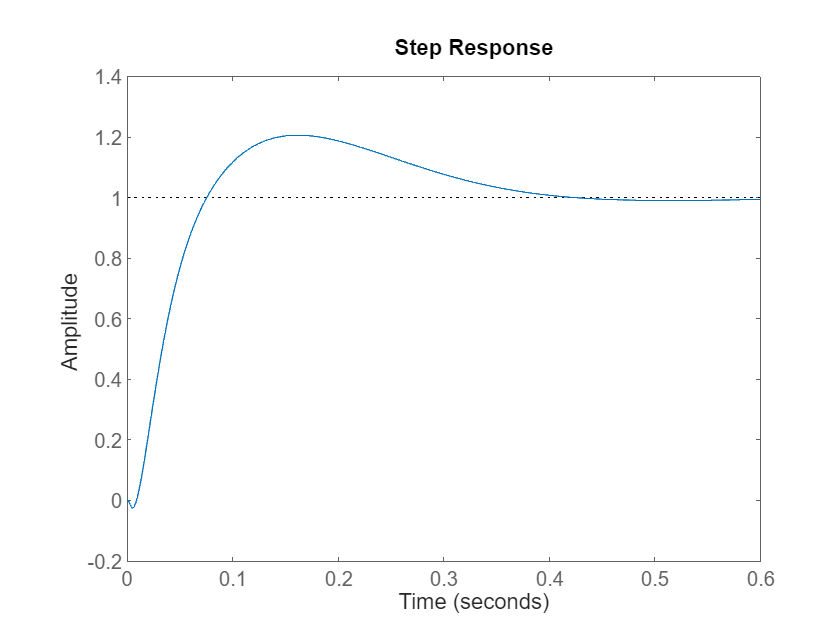

step(feedback(d2c(lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_tf_z,'zoh')*plant_tf,1));

disp(stepinfo(feedback(d2c(lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_tf_z,'zoh')*plant_tf,1)));

         RiseTime: 0.0475
    TransientTime: 0.3721
     SettlingTime: 0.3731
      SettlingMin: 0.9022
      SettlingMax: 1.2061
        Overshoot: 20.6116
       Undershoot: 2.4959
             Peak: 1.2061
         PeakTime: 0.1615



# Final Controllers

## Double Integrator

integ_ctrl_tf_z_neg = tf(cell2mat(integ_ctrl_tf_z.Numerator),cell2mat(integ_ctrl_tf_z.Denominator),Ts,"variable",'z^-1')

integ_ctrl_tf_z_neg =
 
     0.002 z^-2
  -----------------
  1 - 2 z^-1 + z^-2
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


## Lead Compensator 1

[lead_ctrl1_num,lead_ctrl1_den]=tfdata(zpk(lead_ctrl1_tf_z));
lead_ctrl1_tf_z_neg = tf(cell2mat(lead_ctrl1_num),cell2mat(lead_ctrl1_den),Ts,"variable",'z^-1')

lead_ctrl1_tf_z_neg =
 
  21.66 - 20.6 z^-1
  -----------------
  1 + 0.06731 z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


## Lead Compensator 2

[lead_ctrl2_num,lead_ctrl2_den]=tfdata(zpk(lead_ctrl2_tf_z));
lead_ctrl2_tf_z_neg = tf(cell2mat(lead_ctrl2_num),cell2mat(lead_ctrl2_den),Ts,"variable",'z^-1')

lead_ctrl2_tf_z_neg =
 
  6.273 - 5.602 z^-1
  ------------------
   1 - 0.4837 z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


## Equivalent Controller


final_ctrl_tf_z = lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_tf_z;
[num,den] = tfdata(zpk(final_ctrl_tf_z));
final_ctrl_tf_neg_z = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

final_ctrl_tf_neg_z =
 
         0.2718 z^-2 - 0.5012 z^-3 + 0.2308 z^-4
  ------------------------------------------------------
  1 - 2.416 z^-1 + 1.8 z^-2 - 0.3513 z^-3 - 0.03255 z^-4
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


final_ctrl_num = cell2mat(final_ctrl_tf_neg_z.Numerator);
final_ctrl_den= cell2mat(final_ctrl_tf_neg_z.Denominator);